% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc; 
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-09-26/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Serum1(40x,495mW,1)_1500_40_2024-09-26-14.55.27.570.csv";
file_path = data_path+file_name;
blood_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum2(40x,495mW,1)_1500_40_2024-09-26-14.57.02.410.csv";
file_path = strcat(data_path,file_name);
blood_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum3(40x,495mW,1)_1500_40_2024-09-26-14.58.36.307.csv";
file_path = strcat(data_path,file_name);
blood_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum4(40x,495mW,1)_1500_40_2024-09-26-15.00.03.367.csv";
file_path = strcat(data_path,file_name);
blood_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum5(40x,495mW,1)_1500_40_2024-09-26-15.01.35.033.csv";
file_path = strcat(data_path,file_name);
blood_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum6(40x,495mW,1)_1500_40_2024-09-26-15.03.07.620.csv";
file_path = strcat(data_path,file_name);
blood_6 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum7(40x,495mW,1)_1500_40_2024-09-26-15.04.40.257.csv";
file_path = strcat(data_path,file_name);
blood_7 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum8(40x,495mW,1)_1500_40_2024-09-26-15.06.11.690.csv";
file_path = strcat(data_path,file_name);
blood_8 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum9(40x,495mW,1)_1500_40_2024-09-26-15.07.45.250.csv";
file_path = strcat(data_path,file_name);
blood_9 = csvread(file_path, numMetadataRows, 0);

file_name = "Serum10(40x,495mW,1)_1500_40_2024-09-26-15.09.12.770.csv";
file_path = strcat(data_path,file_name);
blood_10 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_200_2024-09-26-14.30.44.597.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_200_2024-09-26-14.26.18.257.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_200_2024-09-26_2024-09-26-14.21.54.970.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
blood_1(:, blood_1(1, :) <= t1) = [];
blood_1(:, blood_1(1, :) >= t2) = [];
blood_2(:, blood_2(1, :) <= t1) = [];
blood_2(:, blood_2(1, :) >= t2) = [];
blood_3(:, blood_3(1, :) <= t1) = [];
blood_3(:, blood_3(1, :) >= t2) = [];
blood_4(:, blood_4(1, :) <= t1) = [];
blood_4(:, blood_4(1, :) >= t2) = [];
blood_5(:, blood_5(1, :) <= t1) = [];
blood_5(:, blood_5(1, :) >= t2) = [];
blood_6(:, blood_6(1, :) <= t1) = [];
blood_6(:, blood_6(1, :) >= t2) = [];
blood_7(:, blood_7(1, :) <= t1) = [];
blood_7(:, blood_7(1, :) >= t2) = [];
blood_8(:, blood_8(1, :) <= t1) = [];
blood_8(:, blood_8(1, :) >= t2) = [];
blood_9(:, blood_9(1, :) <= t1) = [];
blood_9(:, blood_9(1, :) >= t2) = [];
blood_10(:, blood_10(1, :) <= t1) = [];
blood_10(:, blood_10(1, :) >= t2) = [];

shifts = wavenumber;

blood1 = blood_1(2:end, :);
blood2 = blood_2(2:end, :);
blood3 = blood_3(2:end, :);
blood4 = blood_4(2:end, :);
blood5 = blood_5(2:end, :);
blood6 = blood_6(2:end, :);
blood7 = blood_7(2:end, :);
blood8 = blood_8(2:end, :);
blood9 = blood_9(2:end, :);
blood10 = blood_10(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

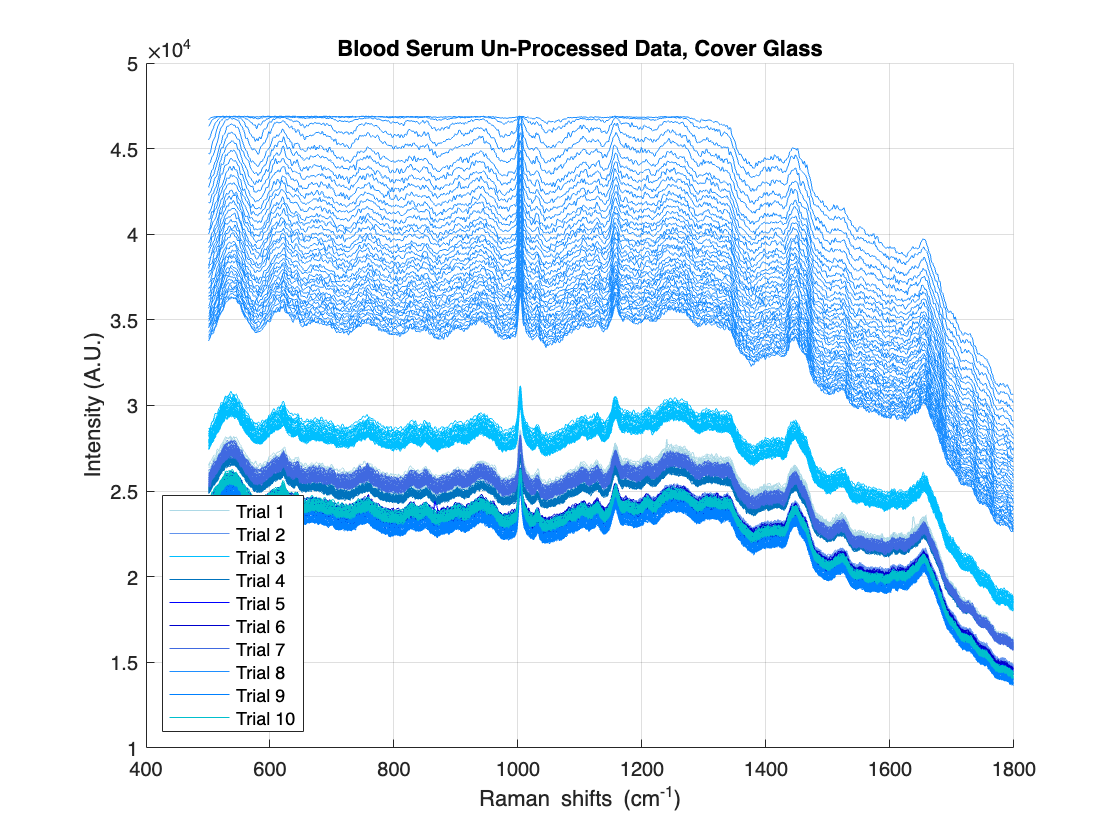

% Plotting unprocessed data

figure;
hold on;
grid on;

% Different shades of blue for the plots
plot(wavenumber, blood1(1,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(1,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(1,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(1,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(1,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(1,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(1,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(1,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(1,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(1,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

plot(wavenumber, blood1(2:end,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(2:end,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(2:end,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(2:end,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(2:end,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(2:end,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(2:end,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(2:end,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(2:end,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(2:end,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Serum Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1 = apply(blood1, [6,1,10,11,8,2,5,6,7]);
pro_blood2 = apply(blood2, [6,1,10,11,8,2,5,6,7]);
pro_blood3 = apply(blood3, [6,1,10,11,8,2,5,6,7]);
pro_blood4 = apply(blood4, [6,1,10,11,8,2,5,6,7]);
pro_blood5 = apply(blood5, [6,1,10,11,8,2,5,6,7]);
pro_blood6 = apply(blood6, [6,1,10,11,8,2,5,6,7]);
pro_blood7 = apply(blood7, [6,1,10,11,8,2,5,6,7]);
pro_blood8 = apply(blood8, [6,1,10,11,8,2,5,6,7]);
pro_blood9 = apply(blood9, [6,1,10,11,8,2,5,6,7]);
pro_blood10 = apply(blood10, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

% blood = [blood1;blood2;blood3;blood4;blood5;blood6;blood7;blood8;blood9;blood10];
% pro_blood = apply(blood, [6,1,10,11,8,2,5,6,7]);

blood = [blood1;blood2;blood4;blood5;blood6;blood7;blood9;blood10];
pro_blood = apply(blood, [6,1,10,11,8,2,5,6,7]);

shifts1 = corr_shifts;

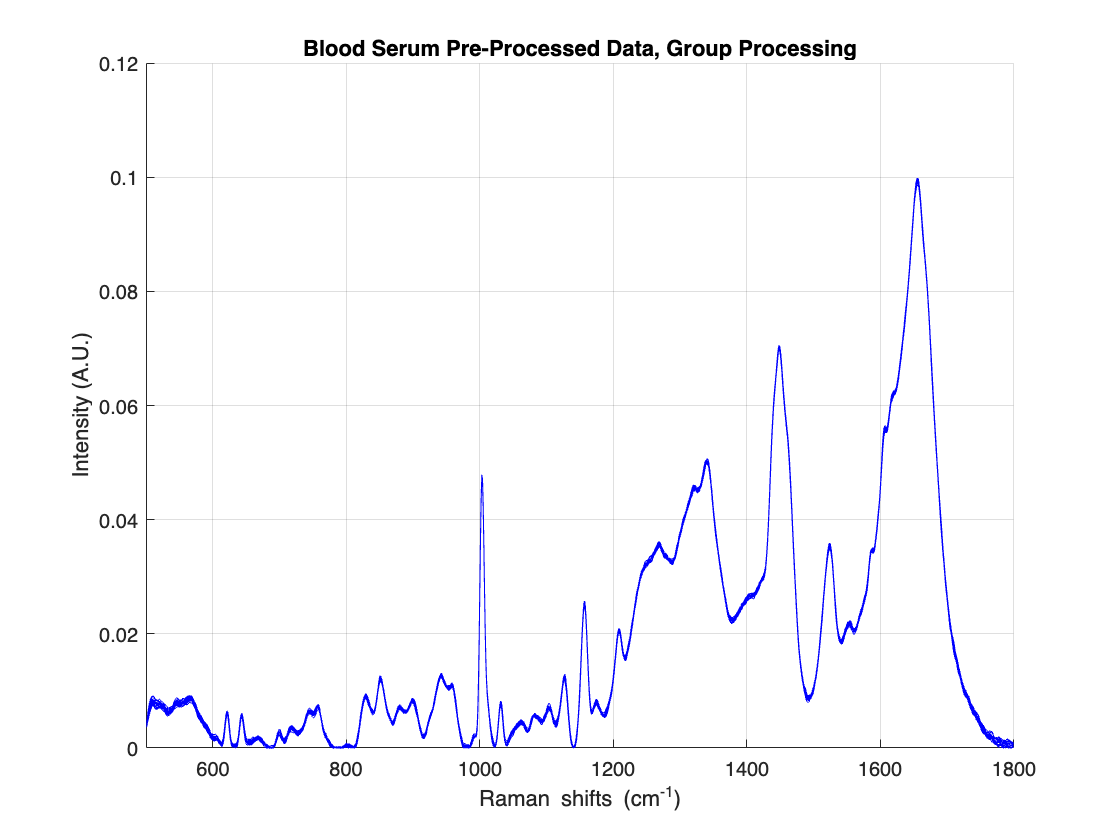

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood, '-b');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Serum Pre-Processed Data, Group Processing');
xlim([500 1800]);
ylim([0 0.12]);
hold off;

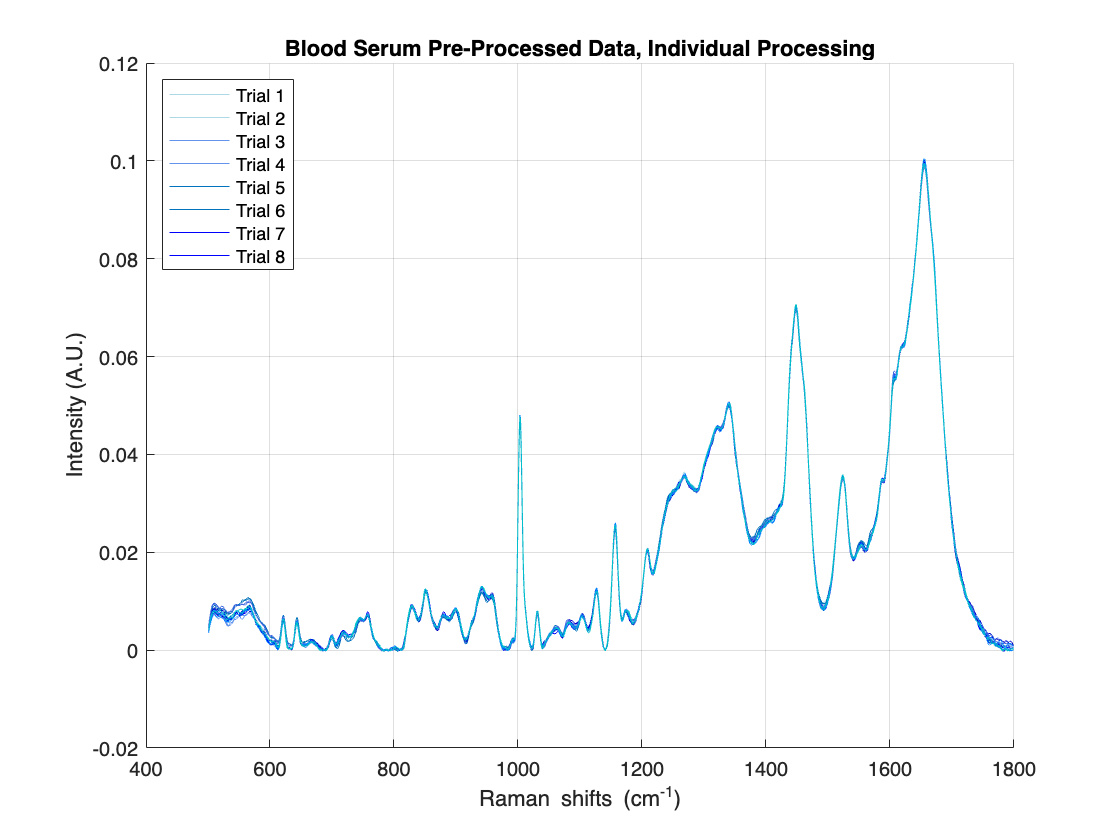

figure;
hold on;
grid on;

% Different shades of blue for the plots
plot(wavenumber, pro_blood1, 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, pro_blood2, 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
%plot(wavenumber, pro_blood3, 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, pro_blood4, 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, pro_blood5, 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, pro_blood6, 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, pro_blood7, 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
%plot(wavenumber, pro_blood8, 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, pro_blood9, 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, pro_blood10, 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Serum Pre-Processed Data, Individual Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'Location', 'northwest');
hold off;

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-08-09/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Sample A data

file_name = "Blood_Plasma1(40x,495mW,A)_2000_30_2024-08-09-12.09.32.687.csv";
file_path = data_path+file_name;
blood_1_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,A)_2000_30_2024-08-09-12.11.14.140.csv";
file_path = strcat(data_path,file_name);
blood_2_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,A)_2000_30_2024-08-09-12.12.39.517.csv";
file_path = strcat(data_path,file_name);
blood_3_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,A)_2000_30_2024-08-09-12.14.03.367.csv";
file_path = strcat(data_path,file_name);
blood_4_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,A)_2000_30_2024-08-09-12.15.28.997.csv";
file_path = strcat(data_path,file_name);
blood_5_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,A)_2000_30_2024-08-09-12.16.56.707.csv";
file_path = strcat(data_path,file_name);
blood_6_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,A)_2000_30_2024-08-09-12.18.22.553.csv";
file_path = strcat(data_path,file_name);
blood_7_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,A)_2000_30_2024-08-09-12.19.55.947.csv";
file_path = strcat(data_path,file_name);
blood_8_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,A)_2000_30_2024-08-09-12.21.21.380.csv";
file_path = strcat(data_path,file_name);
blood_9_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,A)_2000_30_2024-08-09-12.22.50.393.csv";
file_path = strcat(data_path,file_name);
blood_10_A8 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-08-09-11.32.18.683.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-08-09-11.27.43.780.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-08-09-11.22.46.103.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_A8(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_A8(:, blood_1_A8(1, :) <= t1) = [];
blood_1_A8(:, blood_1_A8(1, :) >= t2) = [];
blood_2_A8(:, blood_2_A8(1, :) <= t1) = [];
blood_2_A8(:, blood_2_A8(1, :) >= t2) = [];
blood_3_A8(:, blood_3_A8(1, :) <= t1) = [];
blood_3_A8(:, blood_3_A8(1, :) >= t2) = [];
blood_4_A8(:, blood_4_A8(1, :) <= t1) = [];
blood_4_A8(:, blood_4_A8(1, :) >= t2) = [];
blood_5_A8(:, blood_5_A8(1, :) <= t1) = [];
blood_5_A8(:, blood_5_A8(1, :) >= t2) = [];
blood_6_A8(:, blood_6_A8(1, :) <= t1) = [];
blood_6_A8(:, blood_6_A8(1, :) >= t2) = [];
blood_7_A8(:, blood_7_A8(1, :) <= t1) = [];
blood_7_A8(:, blood_7_A8(1, :) >= t2) = [];
blood_8_A8(:, blood_8_A8(1, :) <= t1) = [];
blood_8_A8(:, blood_8_A8(1, :) >= t2) = [];
blood_9_A8(:, blood_9_A8(1, :) <= t1) = [];
blood_9_A8(:, blood_9_A8(1, :) >= t2) = [];
blood_10_A8(:, blood_10_A8(1, :) <= t1) = [];
blood_10_A8(:, blood_10_A8(1, :) >= t2) = [];

shifts = wavenumber;

blood1_A8 = blood_1_A8(2:end, :);
blood2_A8 = blood_2_A8(2:end, :);
blood3_A8 = blood_3_A8(2:end, :);
blood4_A8 = blood_4_A8(2:end, :);
blood5_A8 = blood_5_A8(2:end, :);
blood6_A8 = blood_6_A8(2:end, :);
blood7_A8 = blood_7_A8(2:end, :);
blood8_A8 = blood_8_A8(2:end, :);
blood9_A8 = blood_9_A8(2:end, :);
blood10_A8 = blood_10_A8(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

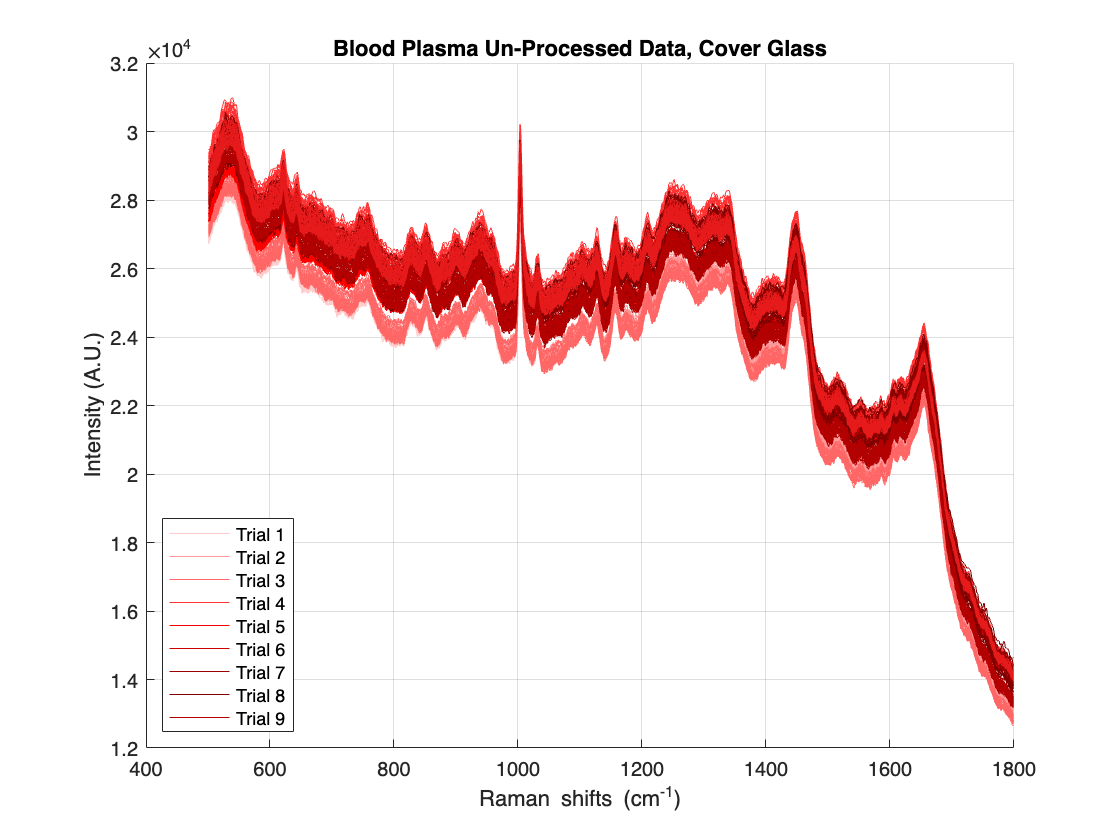

figure;
hold on;
grid on;
plot(wavenumber, blood1_A8(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A8(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_A8(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A8(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1_A8 = apply(blood1_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood2_A8 = apply(blood2_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood3_A8 = apply(blood3_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood4_A8 = apply(blood4_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood5_A8 = apply(blood5_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood6_A8 = apply(blood6_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood7_A8 = apply(blood7_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood8_A8 = apply(blood8_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood9_A8 = apply(blood9_A8, [6,1,10,11,8,2,5,6,7]);
pro_blood10_A8 = apply(blood10_A8, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_A8 = [blood1_A8;blood2_A8;blood3_A8;blood4_A8;blood5_A8;blood6_A8;blood7_A8;blood8_A8;blood9_A8;blood10_A8];
pro_blood_A8 = apply(blood_A8, [6,1,10,11,8,2,5,6,7]);

shifts2 = corr_shifts;

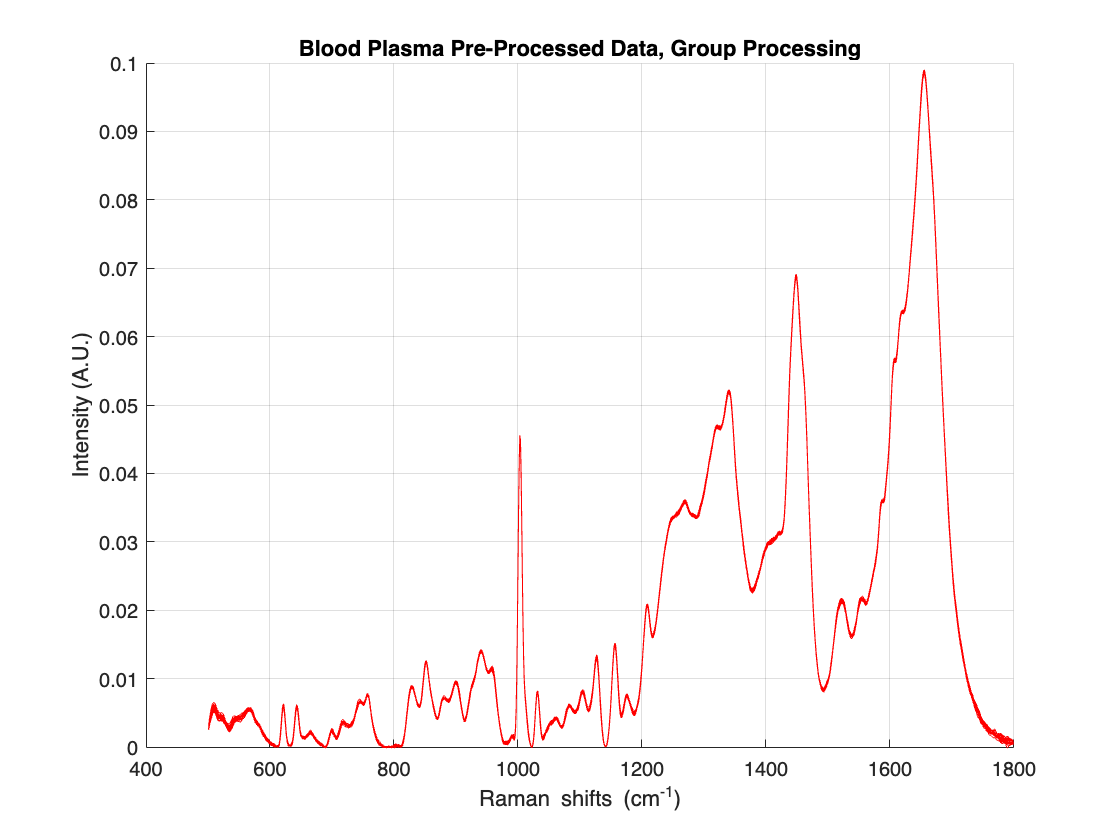

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A8, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

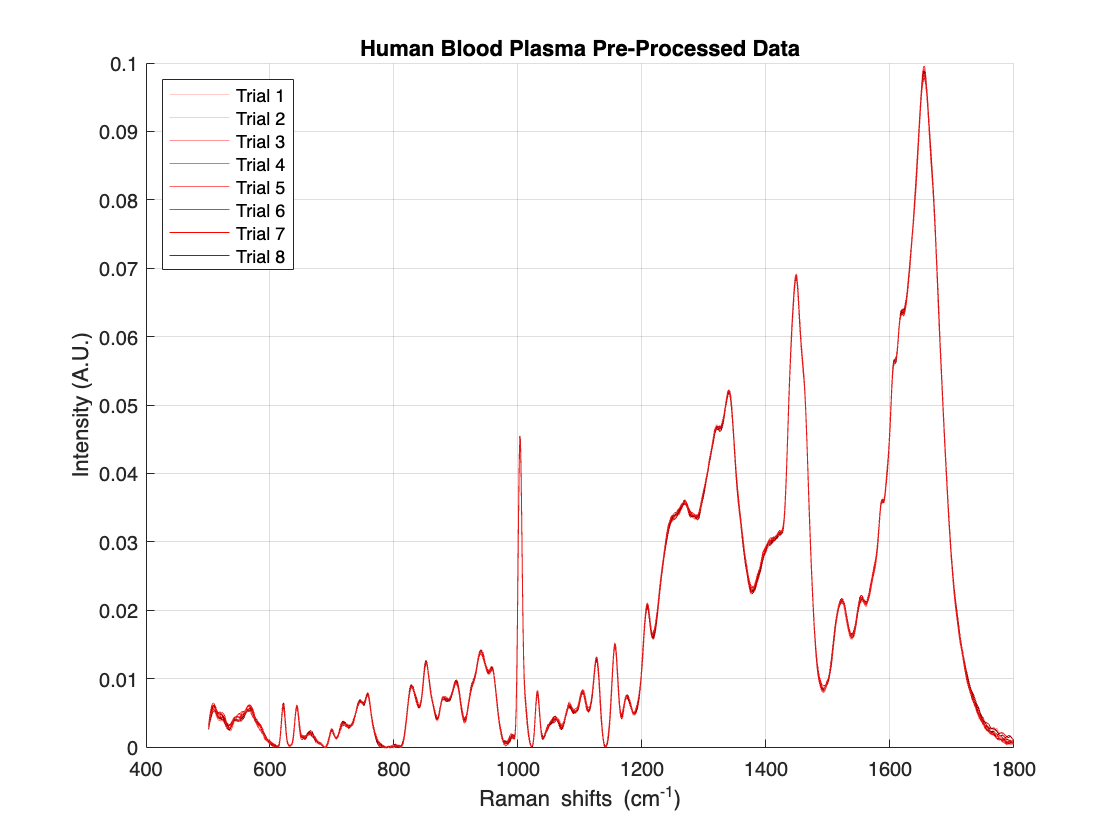

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_A8, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A8, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A8, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A8, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A8, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A8, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A8, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A8, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A8, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_A8, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'Location', 'northwest');
hold off;

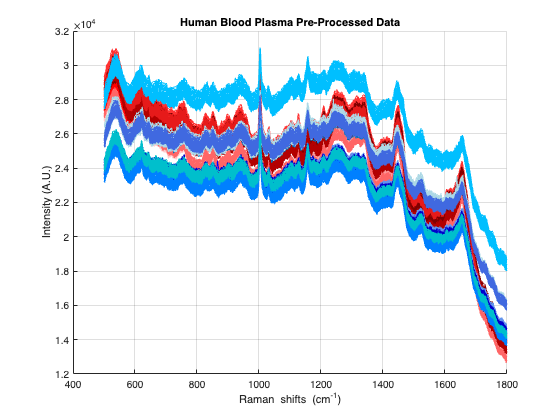

% Comparison between Serum and Blood

figure;
hold on;
grid on;

plot(wavenumber, blood1_A8(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A8(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_A8(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A8(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A8(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A8(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A8(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A8(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A8(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A8(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A8(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A8(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red

% Different shades of blue for the plots
plot(wavenumber, blood1(1,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(1,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
%plot(wavenumber, blood3(1,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(1,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(1,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(1,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(1,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
%plot(wavenumber, blood8(1,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(1,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(1,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

plot(wavenumber, blood1(2:end,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(2:end,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(2:end,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
%plot(wavenumber, blood4(2:end,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(2:end,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(2:end,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(2:end,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
%plot(wavenumber, blood8(2:end,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(2:end,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(2:end,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
hold off;

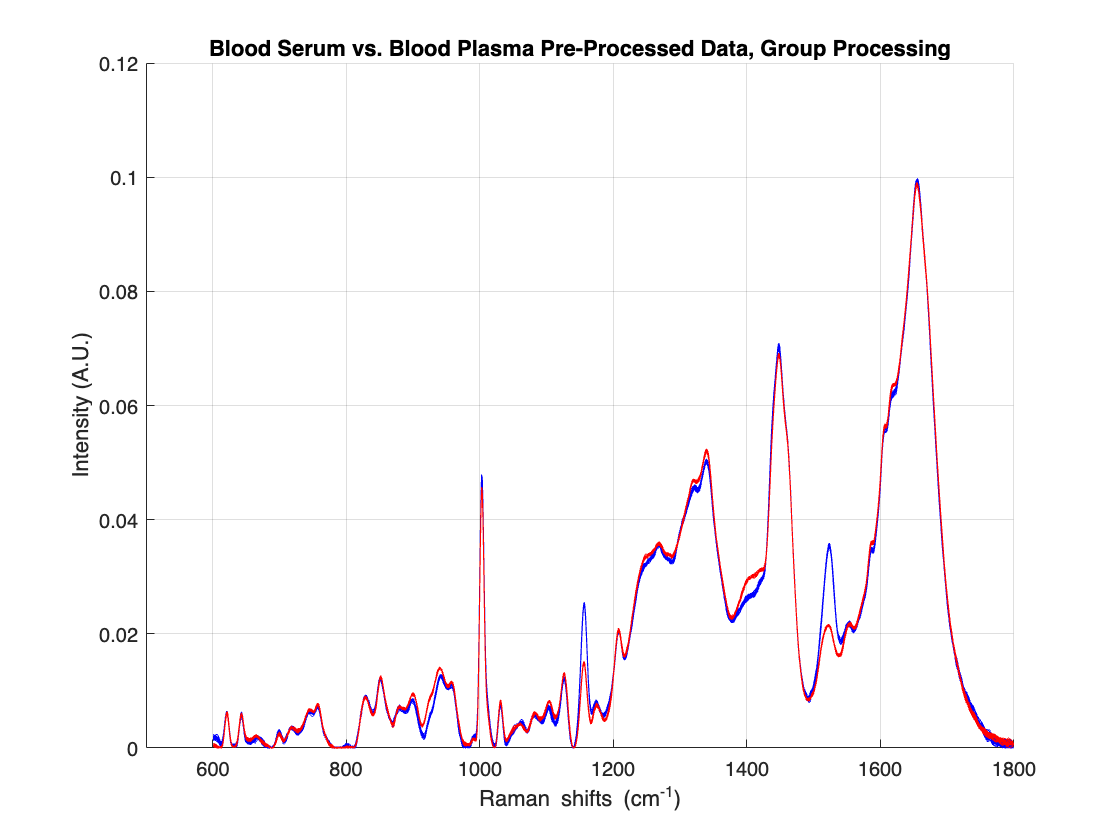

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(shifts1(101:end), pro_blood(:,101:end), '-b');
plot(shifts2(101:end), pro_blood_A8(:,101:end), '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Serum vs. Blood Plasma Pre-Processed Data, Group Processing');
xlim([500 1800]);
ylim([0 0.12]);
hold off;

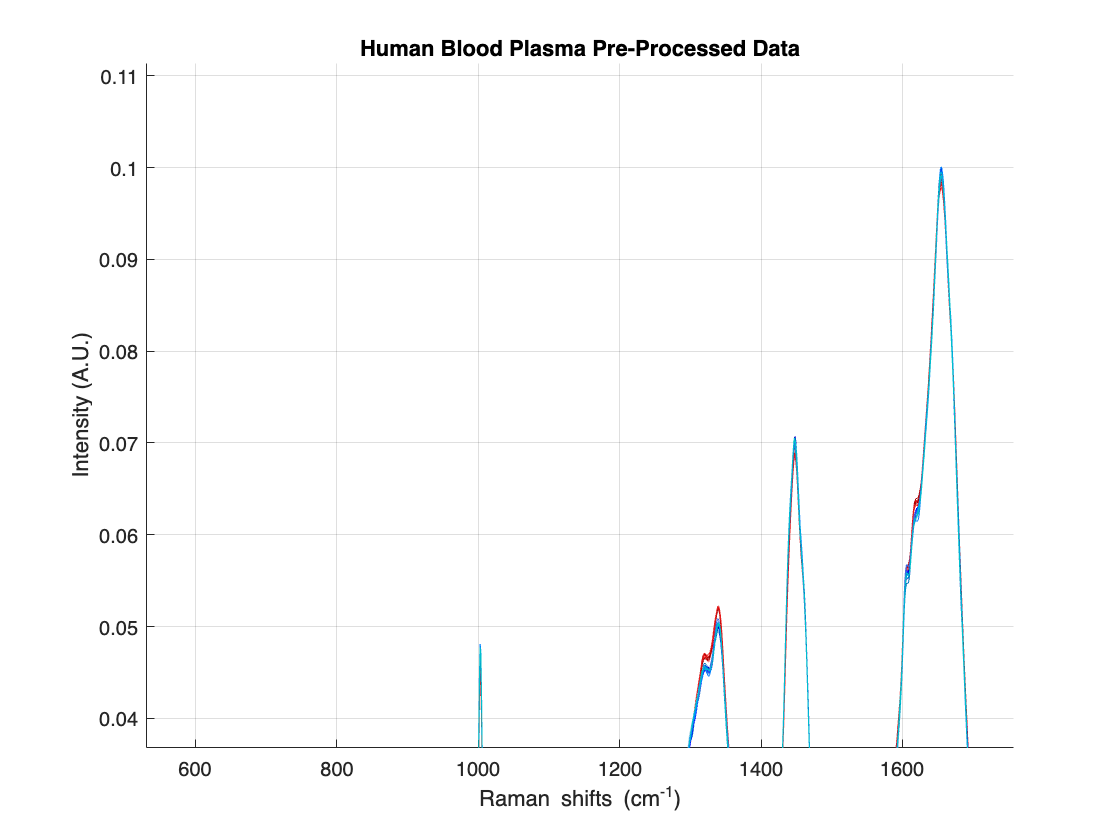

figure;
hold on;
grid on;
plot(corr_shifts, pro_blood1_A8, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(corr_shifts, pro_blood2_A8, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(corr_shifts, pro_blood3_A8, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(corr_shifts, pro_blood4_A8, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(corr_shifts, pro_blood5_A8, 'Color', [1.00, 0.00, 0.00]); % Red
plot(corr_shifts, pro_blood6_A8, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(corr_shifts, pro_blood7_A8, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(corr_shifts, pro_blood8_A8, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(corr_shifts, pro_blood9_A8, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(corr_shifts, pro_blood10_A8, 'Color', [0.90, 0.10, 0.10]); % Light Red
% Different shades of blue for the plots
plot(shifts1, pro_blood1, 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(shifts1, pro_blood2, 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
%plot(shifts1, pro_blood3, 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(shifts1, pro_blood4, 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(shifts1, pro_blood5, 'Color', [0.00, 0.00, 1.00]); % Blue
plot(shifts1, pro_blood6, 'Color', [0.00, 0.00, 0.80]); % Navy
plot(shifts1, pro_blood7, 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
%plot(shifts1, pro_blood8, 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(shifts1, pro_blood9, 'Color', [0.00, 0.50, 1.00]); % Blue
plot(shifts1, pro_blood10, 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');

% Spectral Peak Finding

serum_data = [pro_blood1;pro_blood2;pro_blood3;pro_blood4;pro_blood5;pro_blood6;pro_blood7;pro_blood8;pro_blood9;pro_blood10];

[SNR_serum1, pks_serum,locs_serum] = SNR_maxpk(serum_data,shifts1);

plasma_data = [pro_blood1_A8;pro_blood2_A8;pro_blood3_A8;pro_blood4_A8;pro_blood5_A8;pro_blood6_A8;pro_blood7_A8;pro_blood8_A8;pro_blood9_A8;pro_blood10_A8];

[SNR_plasma1, pks_plasma,locs_plasma] = SNR_maxpk(plasma_data,shifts2);

SNR_serum1

SNR_serum1 =      2.631900319583607e+02


SNR_plasma1

SNR_plasma1 =      2.154309235139287e+02


[SNR_serum2, loc_SNR_serum] = SNR_loc(serum_data,shifts1, 1003);
[SNR_plasma2, loc_SNR_plasma] = SNR_loc(plasma_data,shifts2, 1003);

SNR_serum2

SNR_serum2 =      1.104200230926940e+02


SNR_plasma2

SNR_plasma2 =      1.806479323834325e+02


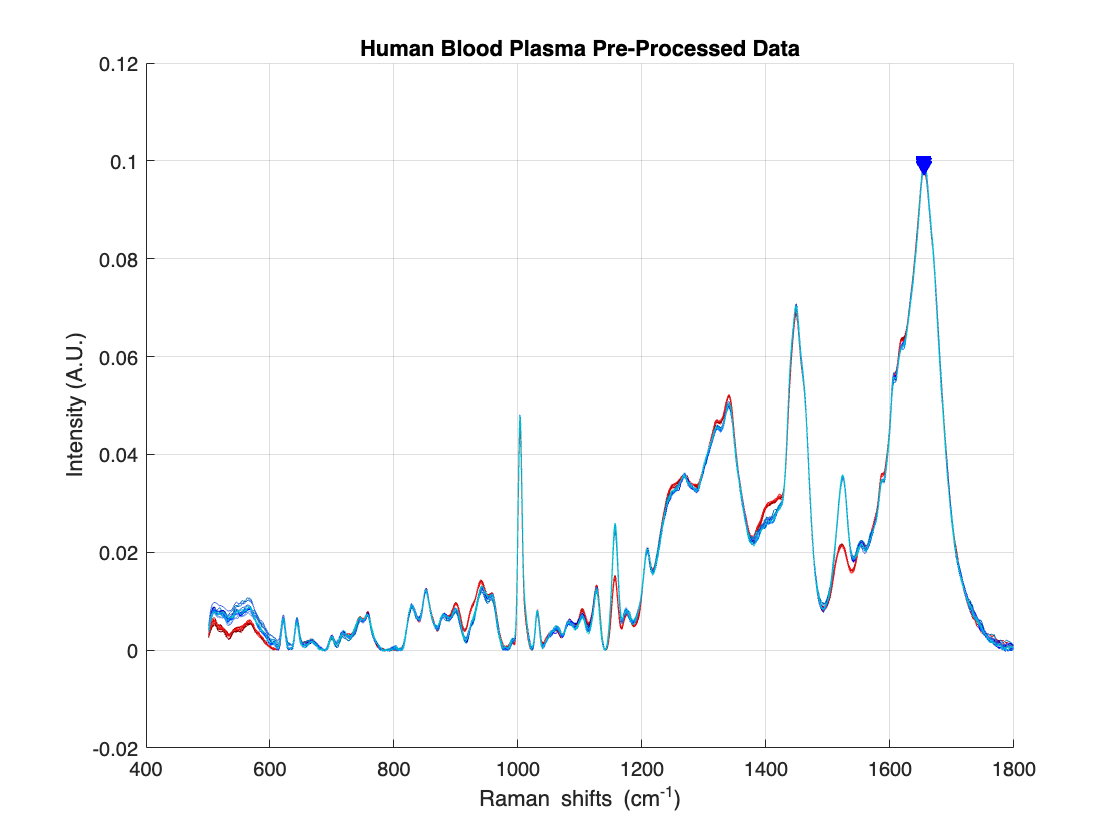

plot(locs_serum, pks_serum, 'bv', 'MarkerFaceColor', [0,0,1]);
hold off;

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = abs((av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2)));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [snr, peaks, locations] = SNR_maxpk(spectra, shifts)

    peaks = zeros(1,size(spectra, 1));
    locations = zeros(1,size(spectra, 1));

    for i = 1:size(spectra, 1)
        [pks, locs] = findpeaks(spectra(i,:), shifts);
        [maxPeak, maxIdx] = max(pks);
        peaks(1,i) = maxPeak;
        locations(1,i) = locs(maxIdx);
    end

    snr = mean(peaks)/std(peaks);

end

function [snr, closestShift] = SNR_loc(spectra, shifts, wavenumber)

    [~, closestIndex] = min(abs(shifts - wavenumber));

    closestShift = shifts(closestIndex);

    peaks = spectra(:, closestIndex);

    snr = mean(peaks)/std(peaks);

end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end




